# IV Praktikum 2022

## `Aufgabe 1`

### `Vorbereitungsteil:`


$$|E| = \frac{1}{\sqrt2} 1V,
 $$
 
$$R_1=R_2=R=50 \Omega$$


#### `1. Bestimmen Sie Pmax.`

 
$$P_{max} = \frac{|E|^2}{4R}$$
     
$$|E|^2 = \left( \frac{1V} {\sqrt{2}} \right)^2$$
 
$$ \Rightarrow  $$
   
$$|E|^2 = \frac{1}{2}V^2
$$


$P_{max} = \frac{\frac{1V^2}{2}}{4R} = \frac{1V^2}{8R} = \frac 1 {400}  \frac {V^2} \Omega
$ $=2,5
$mW  

#### `2. Bestimmen Sie S21(jω).`


$$S_{21} = k \frac {U_2} E = 2 \sqrt \frac{R_1} {R_2} \frac {U_2} {U_1} \frac{U_1} {E}$$
  
$$\Rightarrow$$
 
$$S_{21} = 2 \frac {U_2} E$$



$$U_1 = I * \left( \frac 1 R_2+ {j\omega C} \right)^{-1} \\
I = \frac E {R_{ges}}$$
  
$$\Rightarrow$$
 
$$U_1 = \frac E {R_{ges}} * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \rightarrow  S_{21} = 2 \frac { \left( R_2+ \frac 1 {j\omega C} \right)^{-1}} {R_{ges}}$$



$$R_{ges} =  R + C||R \\
C||R = \frac1 {j \omega C+\frac 1 R}$$
        
$$\Rightarrow
$$
     
$$R_{ges} = R + \frac 1 {j \omega C + \frac 1 R}$$
   
$$\rightarrow$$
 
$$S_{21} = 2 \frac { \left( \frac 1 R+ j\omega C \right)^{-1}} {R+ \frac R {j \omega C R + 1}} $$


syms R omega C real
R_ges = R + 1/(1i*omega*C+1/R);
S_21 = 2*((1/R+1i*omega*C)^-1)/(R+R/(1+1i*omega*C*R)) %2*R/R_ges

$$S\_21 = \frac{2}{\left(\frac{1}{R}+C\,\omega \,\mathrm{i}\right)\,\left(R+\frac{R}{1+C\,R\,\omega \,\mathrm{i}}\right)}$$

simplify(S_21,"Steps",640)

$$ans = \frac{2}{2+C\,R\,\omega \,\mathrm{i}}$$

#### `3. Bestimmen Sie `| `S21(jω)|`² `und AdB(ω).`

simplify(abs(S_21)^2,"Steps",100)

$$ans = \frac{4\,R^{2}\,{\left|C\,R\,\omega -\mathrm{i}\right|}^{2}}{{\left|C\,R\,\omega -2\,\mathrm{i}\right|}^{2}\,{\left|1+C\,R\,\omega \,\mathrm{i}\right|}^{2}\,{\left|R\right|}^{2}}$$

S_21 = 4/(C^2*R^2*omega^2 + 4) - (2i*C*R*omega)/(C^2*R^2*omega^2 + 4)

$$S\_21 = \frac{4}{C^{2}\,R^{2}\,\omega^{2}+4}-\frac{2\,C\,R\,\omega \,\mathrm{i}}{C^{2}\,R^{2}\,\omega^{2}+4}$$

simpS21_abs_quad = (4*C^2*R^2*omega^2)/(C^2*R^2*omega^2 + 4)^2 + 16/(C^2*R^2*omega^2 + 4)^2

$$simpS21\_abs\_quad = \frac{16}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}+\frac{4\,C^{2}\,R^{2}\,\omega^{2}}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}$$

A_db = 10*log10((C^2*R^2*omega^2 + 4)^2/(4*C^2*R^2*omega^2+16))

$$A\_db = \frac{10\,\log\left(\frac{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}{4\,C^{2}\,R^{2}\,\omega^{2}+16}\right)}{\log\left(10\right)}$$

simA_db = simplify(A_db,"Steps",100)

$$simA\_db = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

#### `4. Zeichnen Sie AdB(ω) qualitativ.`

A_dB = symfun(simA_db,[C,R,omega])

$$A\_dB(C, R, omega) = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

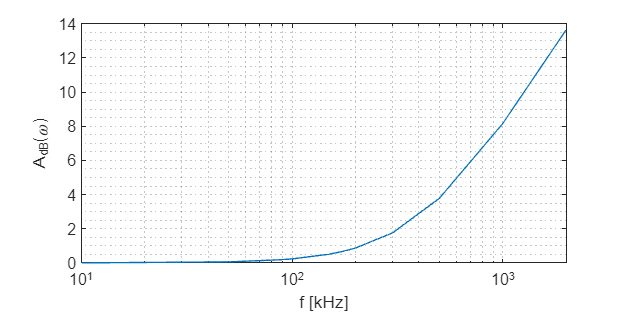

f = [10 50 90 100 150 170 180 200 300 500 1000 2000]*1e3; %kHZ

%f = 1000:1000:2000000;
semilogx(f./10^3,A_dB(15*10^-9,50,2*pi*f)) %C-Wert aus letzte Aufgabe
xlabel ("f [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")
set(gcf,"Position",[0,0,500,250])

#### `5. Handelt es sich um ein Hochpass- oder ein Tiefpassfilter? Begründen Sie Ihre Antwort.`

Tiefpass, da tiefe Frequ. eine geringe Dämpfung haben und hohe Freq. eine hohe Dämpfung.

#### `6. Bestimmen Sie C in Abhängigkeit von der Durchlasskreisfrequenz` $\omega_g$ `und dem Rippel im Durchlassbereich` $A_D$. 

*Nutzen Sie dazu den Ansatz *$A_{dB}(\omega_g) = A_D$. 

syms A_D
formula = solve(simA_db==A_D,C,"ReturnConditions",true);
formula.C(2);


$$C(A_D,\omega) = \frac {2 \sqrt{10^{A_D/10 }-1}} {\omega50 \Omega}$$


#### `7. Bestimmen Sie den Wert von C für f` $(f_g = 100kHz)$ `und` A $(A_D = 0.28dB)$. `Runden Sie Ihr Ergebnis auf den nächsten in der E6-Bauteilreihe1 verfügbaren Wert.`

double(subs(formula.C(2),[A_D R omega], [0.28 50 2*pi*10^5]))*1e9  %%F --> nF

ans = 16.4288


$$C(0.28,\omega = 2\pi f_g) = 16.4288nF$$


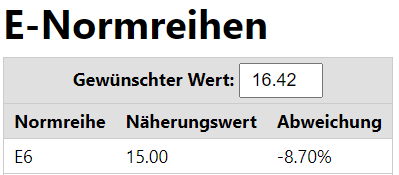

C_value = 15 %nF


$$C_{E6}=15nF$$


### `Praxisteil`

#### `Aufgabe 7 Machen Sie ein Kamerabild von Ihrem Aufbau auf dem Breadboard. Und fügen Sie es dem Bericht bei.` 

Aufbau Bild:

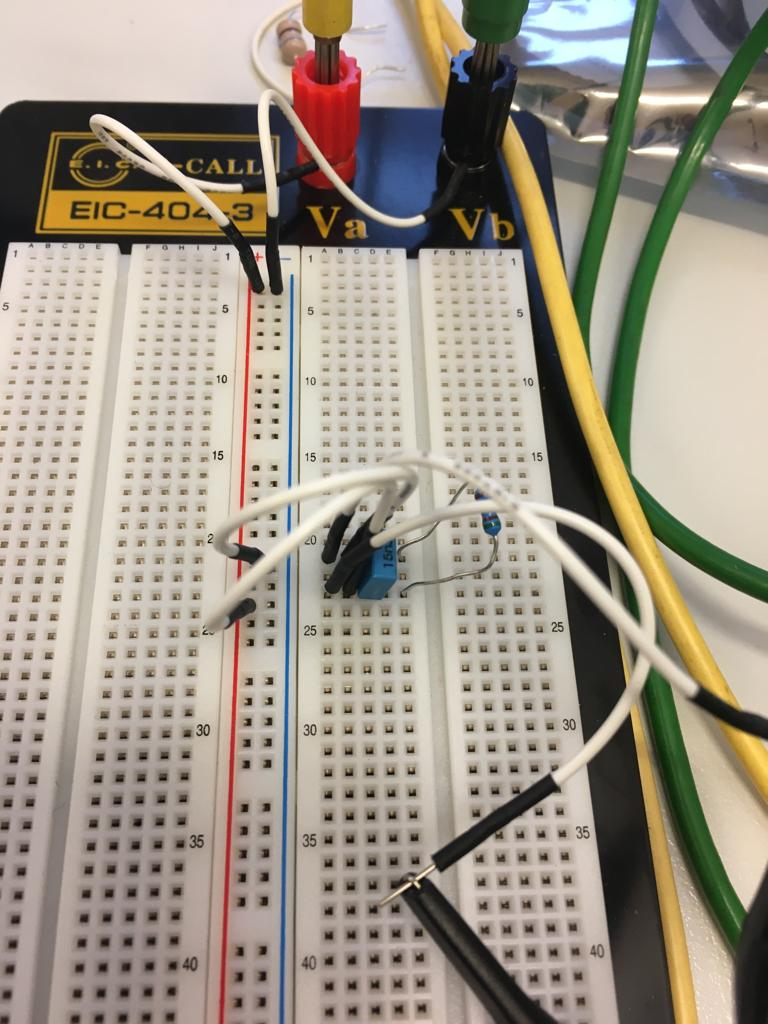

#### `Aufgabe 8/9/11 Beschreiben Sie Ihre Vorgehensweise bei der Einstellung des Oszilloskop:`

Vorgehensweiße:

Zuerst muessen die Vorgegeben Werte auf dem Generator einigestellt werden. 100kHz und 1VPP:

Beim Anschalten des Ozsi. wird das Signal mit dem Auto-Detect Knopf detektiert. Fuer die Ablesung der Amplitude muss noch vertikal rein gezoomt werden.

Die Amplitude hatte ein Wert von 58.8 mW und eine Periodendauer von 10$\mu s$ (siehe Screenshot). 

Periodendauer $10\mu s$

Amplitude: $588 mW$

#### `Aufgabe 10/12 Zeichnen Sie die abgelesene Amplitude und die Periodendauer gut sichtbar in Ihrer Abbildung ein.`     

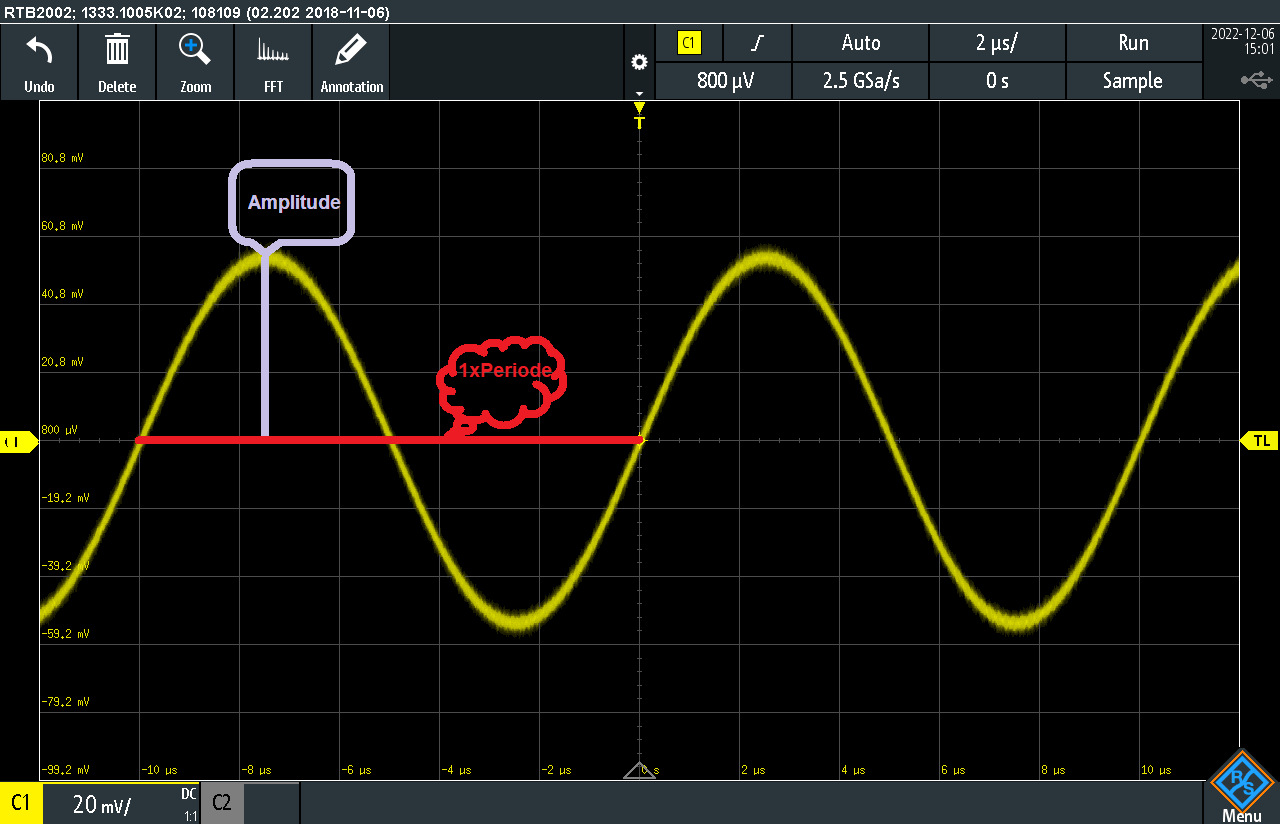

#### `Berechnen ``Sie die Frequenz` $f$ `aus der Periodendauer`

$f _g= \frac 1 {T}$ mit  $T = 10 \mu s$ 


$$f_g = 100 kHz$$


fg = 1/(10^-5)/1000 %kHz

#### `Aufgabe 13 Messen Sie den Betrag von U2 für die in Tabelle 1 aufgelisteten Frequenzen` $f$.

clf
f1 = [10 50 90 100 150 170 180 200 300 500 1000 2000]; %kHZ --Tabelle
Periodendauer = f.^-1*1000; %Mikrosekundend
Amp = [502 498 484 482 462 445.9 440.02 430.22 374.36 273.42 174.44 92.12];
round(Amp*1/sqrt(2),2)


$$U_{eff2}=\hat{U_2} \frac 1 \sqrt{2}$$



$$\begin{array}{l}
\;\hat{U_2 } \left\lbrace \mathrm{mV}\right\rbrace \;\;:502\;\;\;\;\;498\;\;\;\;\;484\;\;\;\;\;482\;\;\;\;\;445\ldotp 9\;\;\;\;\;440\ldotp 02\;\;\;\;\;430\ldotp 22\;\;\;\;\;374\ldotp 36\;\;\;\;\;273\ldotp 42\;\;\;\;\;174\ldotp 44\;\;\;\;\;92\ldotp 12\\
U_{\mathrm{eff2}} \;\left\lbrace \mathrm{mV}\right\rbrace :355\ldotp 97\;\;\;\;\;352\ldotp 14\;\;\;\;\;342\ldotp 24\;\;\;\;\;341\ldotp 83\;\;\;\;\;326\ldotp 68\;\;\;\;\;315\ldotp 3\;\;\;\;\;311\ldotp 14\;\;\;\;\;304\ldotp 21\;\;\;\;\;264\ldotp 71\;\;\;\;\;193\ldotp 34\;\;\;\;\;123\ldotp 35
\end{array}$$


`(Beträge sind auf 2. Nachkommastellen gerundet)`

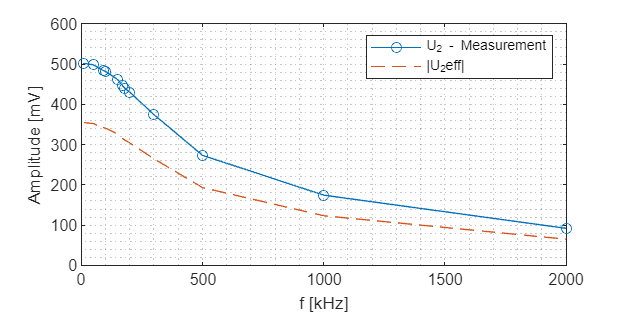

plot(f1,Amp,Marker="o")
hold on
plot(f1,Amp*1/sqrt(2),LineStyle="--")
xlabel("f [kHz]")
ylabel("Amplitude [mV]")
grid("minor")
legend("U_2 - Measurement", "|U_2eff|")
hold off

Mit steigender Frequenz sinkt die Amplitdue. (Tiefpass verhalten)

#### `Aufgabe 14 Rechnen Sie die gemessenen Beträge von` $U_2$ `in Werte der Transmittanz` $|S_{21}(j\omega )|$ `um.`

S21_value = 2*(Amp./sqrt(2))/(1e3/sqrt(2))


$$$|S_{21}| = 2\frac{|U_2|} {|E|}=2 \frac {\hat{U_2}} {\sqrt{2}} \frac \sqrt{2} {E}$$



$${|S}_{21} |:1\ldotp 004\;\;\;\;\;0\ldotp 996\;\;\;\;\;0\ldotp 968\;\;\;\;\;0\ldotp 964\;\;\;\;\;0\ldotp 924\;\;\;\;\;0\ldotp 8918\;\;\;\;\;0\ldotp 88\;\;\;\;\;0\ldotp 8604\;\;\;\;\;0\ldotp 7487\;\;\;\;\;0\ldotp 5468\;\;\;\;\;0\ldotp 3489\;\;\;\;\;0\ldotp 1842$$


#### `Aufgabe 15 Rechnen Sie die Werte von` |S21| `in Werte der Betriebsdämpfung` $A_{dB}(\omega )$ `um`.

clf
A_dB_value = double(10*log10(abs(S21_value).^-2))


$$A_{\textrm{dB}} \;\left\lbrace \textrm{dB}\right\rbrace :\;-0\ldotp 0347\;\;\;\;\;0\ldotp 0348\;\;\;\;\;0\ldotp 2825\;\;\;\;\;0\ldotp 3185\;\;\;\;\;0\ldotp 6866\;\;\;\;\;0\ldotp 9947\;\;\;\;\;1\ldotp 1100\;\;\;\;\;\;1\ldotp 3056\;\;\;\;\;\;2\ldotp 5136\;\;\;\;\;5\ldotp 2428\;\;\;\;\;\;9\ldotp 1465\;\;\;\;\;\;14\ldotp 6923$$


#### `Aufgabe 16 Stellen Sie die Werte von AdB` $A_{dB}(\omega )$ `in einem Diagramm über die Frequenz dar.`

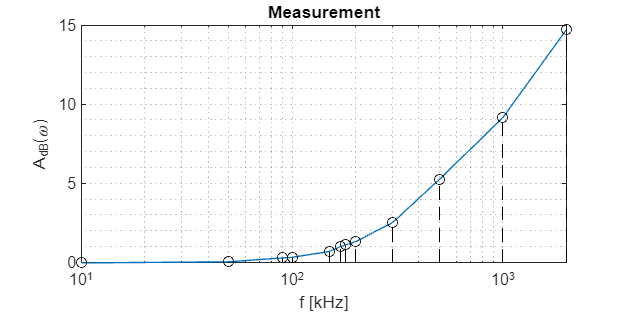

clf
semilogx(f1,A_dB_value)
hold on
stem(f1,A_dB_value, "LineStyle","--","Color", "black")
grid("minor")
xlabel("f [kHz]")
ylabel("A_{dB}(\omega)")
title("Measurement")
hold off

#### `Aufgabe 17 Vergleichen Sie die Darstellung mit dem im Vorbereitungsteil skizzierten Verlauf von AdB.` $A_{dB}(\omega )$.

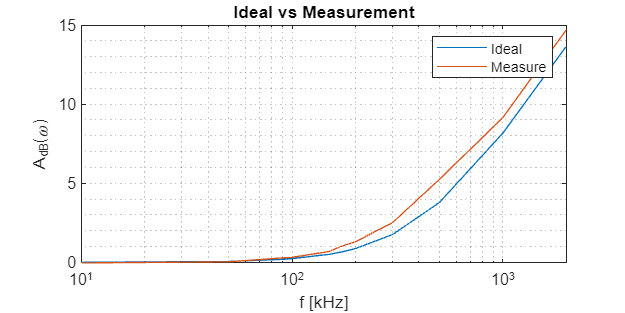

clf
semilogx(f1,A_dB(15*10^-9,50,2*pi*f1*10^3)) %C-Wert aus letzte Aufgabe
xlabel ("f [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")
hold on
semilogx(f1,A_dB_value)
%stem(f1,A_dB_value,"LineStyle","--","Color", "black")
legend("Ideal", "Measure")
title("Ideal vs Measurement")
hold off

Die Verläufe der beiden Skizzen sind gleich. 

Interessant ist die negative Dämpfung am Anfang in den Messwerten. Bei der Qualitativen Skizze ist keine negative Dämpfung vorhanden. Der Grund für das Erscheinen des negativen Wertes beim Messen, ist Messrauschen. 

Dadurch wir das Argument im Log kleiner als 1, was einem negativem Wert entspricht.

## `Aufgabe 2`

### `Vorbereitungsteil:`

#### `1.Entwerfen Sie ein Cauer Tiefpassfilter 3.Ordnung:` $\Omega_S \leq 2$ $a_S \geq 28dB$ $R_1 = R_2 = 50\Omega$

    $\Omega_s \leq 2$, $n=3$ --> C0325 (siehe Filtertabelle)

#### `2. Welche Filterkatalognummer und welches Theta` $\Theta$ `haben Sie gewählt, welches r?` $r_1, r_2$? 

    
$$\Theta = 30\degree $$
 
$$r_1 = r_2 = 1$$


#### `3. Zeichnen Sie den Schaltplan des gewählten Filters.`

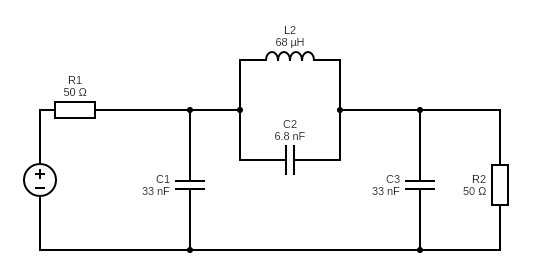

#### `4. Nun sei weiterhin gegeben fs.` $f_S = 200kHz$ `Berechnen Sie die erforderlichen Bauteilwerte des Filters.`

    
$$\Omega_s = \frac {f_s} {f_g}$$
    
$$\longrightarrow$$
 
$$f_g = \frac {f_s}{\Omega_s}$$


f_g = 200/2 %kHz


$$f_g = 100kHz$$


L_0 = 50/(2*pi*f_g)


$$L_0 = \frac{50}{2\pi f_g} =  0.0796mH$$


L_2 = 0.962438*L_0 


$$L_2 = 0.962438*L_0 = 0.0766mH$$


C_0 = 1/(50*2*pi*f_g*10^3)*10^9


$$C_0 = \frac 1 {50^.2\pi f_g} =31.8310mF$$


C_n = [1.203011 0.201627 1.203011]*C_0


$$C_1 = 38.2930nF$$
   
$$C_2 = 6.4180nF$$
   
$$C_3=38.2930nF$$
    

#### `5. Runden Sie die Bauteilwerte auf die nächsten in der E6-Bauteilreihe verfügbaren Werte.` 

**    E6 Bauteil**: $L_2 = 0.068mH$

**    E6 Bauteil: **$C_1 =  33 nF$        $C_2 = 6.8nF$        $C_3=33nF$

#### `6. ``Rechnen Sie die normierte Unendlichkeitsstelle` $\Omega_{\infty2}$ `und Nullstelle` $\Omega_{02}$ `in die zugehörigen Frequenzen` $f_{\infty2}$ $f_{02}$

    
$$\Omega_{\infty 2} = 2.270068086$$
      
$$\Omega_{02} = 0.8810308431$$
      

f_inf2 = 2.270068086*f_g %kHz
f_02 = 0.88103008431*f_g %kHz

    
$$\Omega_{\infty2} = \frac {f_{\infty2}} {f_g}$$
        
$$\Rightarrow$$
        
$$f_{\infty2} = \Omega_{\infty2} \cdot f_g = 227.0068kHz$$
         

    
$$\Omega_{02} = \frac {f_{02}} {f_g}$$
          
$$\Rightarrow$$
       
$$f_{02} = \Omega_{02} \cdot f_g = 88.1030kHz$$


### `Praxisteil`

#### 2. Machen Sie ein Kamerabild von Ihrem Aufbau auf dem Breadboard und fügen Sie es dem Bericht bei.

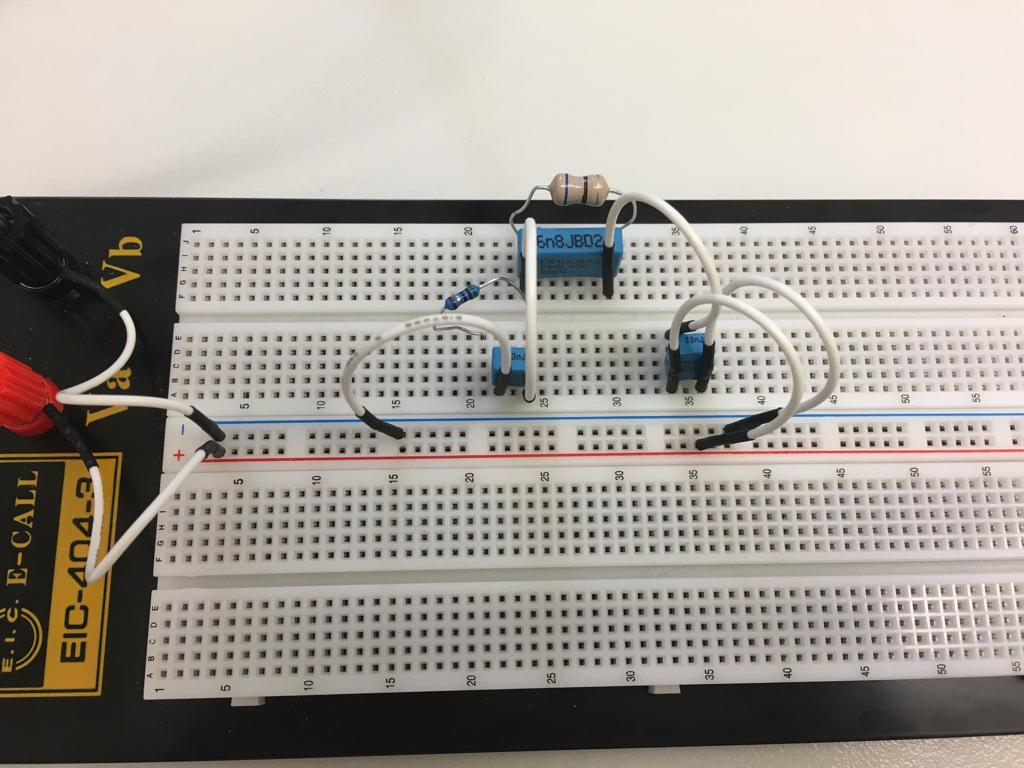

#### 3. Messen Sie den Betrag von U2 für die in Tabelle 2 aufgelisteten Frequenzen f.

U2f_inf = 10.29/2;
U2f_02 = 968/2;

f                = [10   50 f_02 90 100 150    170    180  200    f_inf2  300    500    1000 2000]; %kHZ --Tabelle
cauer_Amp        = [494 480  U2f_02 486 484 211.19 110.25 77.8 35.966    U2f_inf  21.658 24.206 4.263 1.323]%mV
round(cauer_Amp*1/sqrt(2),2)


$${\hat{U} }_2 \;\left\lbrace \mathrm{mV}\right\rbrace :\;494\;\;\;\;\;480\;\;\;\;\;484\;\;\;\;\;486\;\;\;\;\;484\;\;\;\;\;211\ldotp 19\;\;\;\;\;110\ldotp 25\;\;\;\;\;77\ldotp 8\;\;\;\;\;35\ldotp 966\;\;\;\;\;5\ldotp 1450\;\;\;\;\;21\ldotp 6580\;\;\;\;\;24\ldotp 2060\;\;\;\;\;4\ldotp 2630\;\;\;\;\;1\ldotp 3230$$



$$\;U_{\mathrm{eff2}} \;\left\lbrace \mathrm{mV}\right\rbrace \;:349\ldotp 31\;\;\;\;\;339\ldotp 41\;\;\;\;\;342\ldotp 24\;\;\;\;\;343\ldotp 65\;\;\;\;\;342\ldotp 24\;\;\;\;\;149\ldotp 33\;\;\;\;\;77\ldotp 96\;\;\;\;\;55\ldotp 01\;\;\;\;\;25\ldotp 43\;\;\;\;\;3\ldotp 64\;\;\;\;\;15\ldotp 31\;\;\;\;\;17\ldotp 12\;\;\;\;\;3\ldotp 01\;\;\;\;\;0\ldotp 94$$


`(Beträge sind auf 2. Nachkommastellen gerundet)`

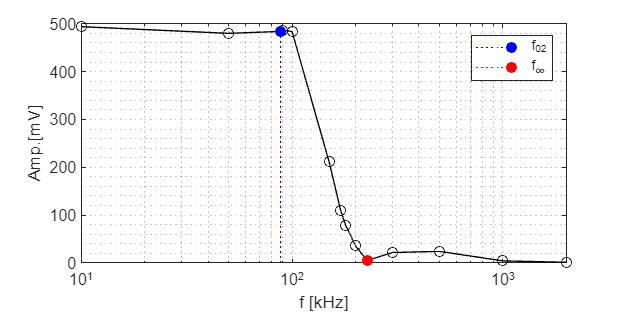

clf
semilogx(f,cauer_Amp,"LineStyle","-","Marker","o","Color","black")
grid minor
hold on
stem(f(3),cauer_Amp(3),"filled",LineStyle=":",Color="b")
stem(f(10),cauer_Amp(10),"filled",LineStyle=":",Color="r")
legend("","f_{02}","f_\infty")
xlabel("f [kHz]")
ylabel("Amp.[mV]")

hold off

#### 4. Messen Sie den Betrag von U2 an der Unendlichkeitsstelle f∞2 und Nullstelle f02. 

U2f_inf = 10.29/2
U2f_02 = 968/2


$$U_{2\infty} = 5.1450mV$$



$$U_{2f_{02}} = 484mV$$


#### 5. Auswertung: Rechnen Sie die gemessenen Beträge von U2 in Werte der Transmittanz |S21(jω)| um. 

cauer_S21 = 2*(cauer_Amp/sqrt(2))/(1e3/sqrt(2))

    
$${|S}_{21} |:0\ldotp 988\;\;\;\;\;0\ldotp 96\;\;\;\;\;0\ldotp 968\;\;\;\;\;0\ldotp 972\;\;\;\;\;0\ldotp 968\;\;\;\;\;0\ldotp 4224\;\;\;\;\;0\ldotp 2205\;\;\;\;\;0\ldotp 1556\;\;\;\;\;0\ldotp 0719\;\;\;\;\;0\ldotp 0103\;\;\;\;\;0\ldotp 0433\;\;\;\;\;0\ldotp 0484\;\;\;\;\;0\ldotp 0085\;\;\;\;\;0\ldotp 0026$$


#### 6. Rechnen Sie die Werte von |S21(jω)| in Werte der Betriebsd¨ampfung AdB(ω) um.

cauerA_dB = 10*log10(cauer_S21.^-2)


$$\mathrm{Cauer}\;A_{\mathrm{dB}\;} \left\lbrace \mathrm{dB}\right\rbrace :0\ldotp 1049\;\;\;\;\;0\ldotp 3546\;\;\;\;\;0\ldotp 2825\;\;\;\;\;0\ldotp 2467\;\;\;\;\;0\ldotp 2825\;\;\;\;\;7\ldotp 4859\;\;\;\;\;13\ldotp 1318\;\;\;\;\;16\ldotp 1598\;\;\;\;\;22\ldotp 8616\;\;\;\;\;39\ldotp 7517\;\;\;\;\;27\ldotp 2670\;\;\;\;\;26\ldotp 3009\;\;\;\;\;41\ldotp 3851\;\;\;\;\;51\ldotp 5482$$


#### 7. Stellen Sie die Werte von AdB(ω) mit den Werten von Aufgabe 1 in einem Diagramm über der Frequenz dar.

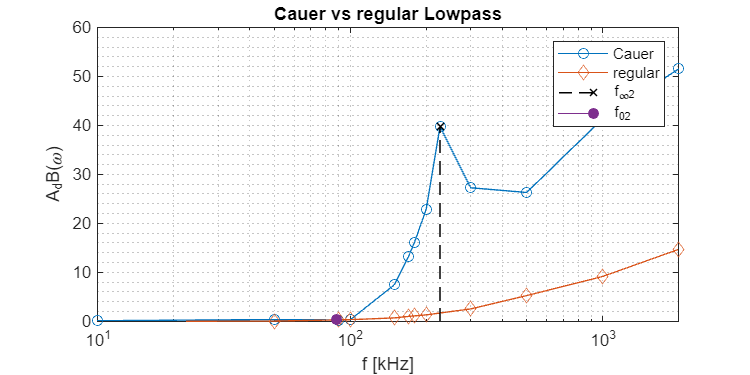

clf
semilogx(f,cauerA_dB,Marker="o")
grid minor
xlabel("f [kHz]")
ylabel("A_dB(\omega)")
hold on
semilogx(f1,A_dB_value,Marker="diamond")
stem(f_inf2,10*log10((2*U2f_inf*10^-3)^-2),"blackX",LineWidth=1,LineStyle="--")
stem(f_02, 10*log10((2*U2f_02*10^-3)^-2),"filled","O")
ylim([0,60])
%stem(f,cauerA_dB,LineStyle="--",Marker="o")
title("Cauer vs regular Lowpass")
%yline(26.5,"LineStyle","--","LineWidth",1,"Label",26.5)
legend("Cauer","regular","f_{\infty2}", "f_{02}")
hold off

%xlim([0,100])
set(gcf,"position",[0,0,600,300])

#### 8.Vergleichen Sie die beiden Verläufe von AdB(ω) von den zwei Aufgaben

Der reguläre Tiefpass ist monoton steigend, während der Cauer-Tiefpass "Rippeln" aufweißt und danach rasant steigt.  Nach dem ersten Peak, fällt der Cauer-Filter kurz und steigt dann weiter an. Als Intepreation des Verhaltens ist, dass die Dämpfung wächst mit zunehmender Frequenz. Bei dem regulären Filter kann bis zum Ende eine Spannung von ca. 100mV gemessen werden. Es zeigt wie schlecht der Tiefpass im vergleich zum Cauer performt. 

**Für kleine Frequenzen**

Sowohl der Cauer Filter, als auch der reguläre Filter weißen eine niedrige Dämpfung (<1dB) auf.

Beim Cauer-Filter treten Schwankungen (auch genannt ,,Rippel") auf, während beim regulären Filter eine** steigende monotonie** zusehen ist. *(zweite A_dB Wert: 0.0348 ausgeschlossen, wegen Messfehler)*

**Für große Frequenzen**

Der Cauer-Filter zeigt eine große Dämpfung für große Frequenzen im Vergleich zum reguläre Tiefpass.

Beim Cauer-Filter beobachtet nach der Sperrfrequenz (ca. 227kHz) einen kurzen Abfall und dann wieder einen Anstieg. Beim regulären Tiefpass weiterhin erkennt man weiterhin eine langsame steigende monotonie.

**Durchlassbereich****: **Beim Cauer Filter ist der Bereich klar definiert und erkennbar $(\leq 10^2 kHz)$ und beim regulären Tiefpass nicht.

**Sperrbereich****: **Der reguläre Tiefpass zeigt keine signifikanten Bereich, wo die Dämpfung sehr hoch ist.  Cauer-Filtersperrt ab ca.$220kHz$

**Steilheit der Verläufe:**

Beim ***Cauer-Filter*** treten bis zum Durchlassbereich kleine Schwankungen auf, danach steigt es rasant an und einen hat einen Peak. Daraufhin fällt es leicht wieder nach unten und steigt wieder. Zusammenegefasst, hat es kleine Schwankungen bis zum Durchlassbereich und große Schwankungen nach dem Sperrbereich.

Die rasante Steilheit des Cauer-Filters ist durch den Schwingkreis gegeben. LC-Schwingkreis wird an der Polstelle unendlich groß, wo durch ein Leerlauf $(U_2=0)$ entsteht. Im Argument vom Log wird nahe 0 $(S_{21}=0)$ geteilt, wodurch große Werte für die Dämpfung [Formel: $A_{dB}=20log(\frac 1 {|S_{21}|})$] entstehen und der Log für unendlich ist unendlich.

Beim ***reguläre Filter ***erkennt man durchgehend, eine Stetigkeit in Kombination mit einer langsamen, steigenden Monotonie. 

--------------------------------------------------------------------------------------------------------------

Kurz: 

Cauer--> schnell, große Dämpfung und ,,Ripple" im Durchlassbereich 

Regulär --> stetig,langsam, monoton steigend, kleine Dämpfung (im Vgl. zum Cauer)  

--------------------------------------------------------------------------------------------------------------

#### 9. Vergleichen Sie den Verlauf von AdB(ω) mit dem Dämpfungsverlauf von dem Filterkatalog an der Nullstelle f02 und der Unendlichkeitsstelle f∞2.

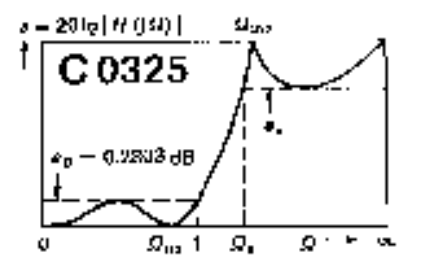

Wenn man in den gemessenen Plot reinzommt dann sieht man die Rippels die einen Cauer Filter kennzeichnen. Zu dem sollten eigentlich Polstellen auftauchen, aber um Polstellen in der Dämpfungsskizze zu erhalten müsste man in der Dämpfungsformel $A_{dB}=20log(\frac {1} {|S_{21}|})$ im Argument durch nahe 0 $(=S_{21})$ teilen bzw 0. Da wir stets Messfehler+Messrauschen und nicht mit idealen Bedingungen arbeiten, erhalten wir immer +/- Werte die stets von 0 abweichen.

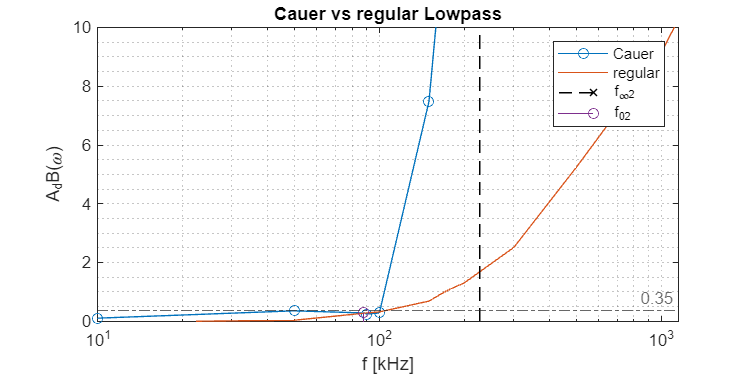

clf
semilogx(f,cauerA_dB,Marker="o")
grid minor
xlabel("f [kHz]")
ylabel("A_dB(\omega)")
hold on
semilogx(f1,A_dB_value)
stem(f_inf2,10*log10((2*U2f_inf*10^-3)^-2),"blackX",LineWidth=1,LineStyle="--")
stem(f_02, 10*log10((2*U2f_02*10^-3)^-2),"O")
yline(0.35,LineStyle="-.",Label=0.35)
ylim([0,10])
title("Cauer vs regular Lowpass")
%yline(26.5,"LineStyle","--","LineWidth",1,"Label",26.5)
legend("Cauer","regular","f_{\infty2}", "f_{02}")
hold off

#### 10. Werden die Anforderungen an den Filterentwurf in der Praxis erfüllt? Bestimmen Sie die tatsächlichen Werte von aS und ΩS aus Ihren Messwerten und vergleichen Sie diese mit den Anforderungen.

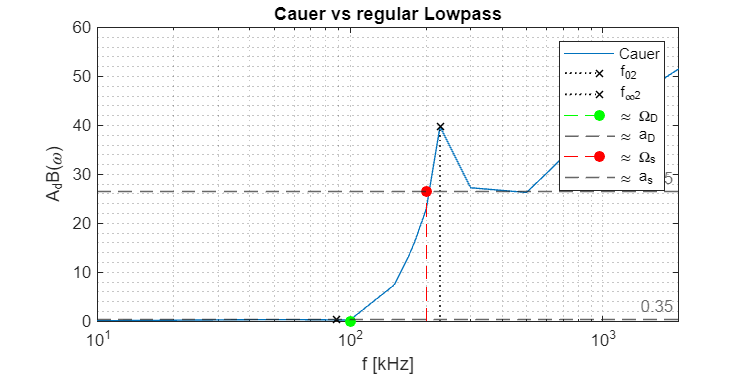

clf
semilogx(f,cauerA_dB)
hold on
stem(f_02, 10*log10((2*U2f_02*10^-3)^-2),"blackX",LineWidth=1,LineStyle=":")
stem(f_inf2,10*log10((2*U2f_inf*10^-3)^-2),"blackX",LineWidth=1,LineStyle=":")
stem(100,0,"filled","LineStyle","--","Color","g")
yline(0.35,"LineStyle","--","LineWidth",1,"Label",0.35)

stem(200,26.5,"filled","LineStyle","--","Color","r")
grid minor
xlabel("f [kHz]")
ylabel("A_dB(\omega)")
hold on
ylim([0,60])
title("Cauer vs regular Lowpass")
yline(26.5,"LineStyle","--","LineWidth",1,"Label",26.5)


legend("Cauer", "f_{02}", "f_{\infty2}", "\approx \Omega_D", "\approx a_{D}", "\approx \Omega_{s}", "\approx a_{s}")

hold off

Anforderung: $a_s \geq 28dB$  

gemessen: $a_s \approx 26.5dB$ 

 
$$\Omega_{\infty2} = 2,27$$
 

Messung  $\Omega_{\infty2} =\frac {f_{\infty2}} {f_g}=\frac {200kHz} {100kHz}=2$        

`Anforderungen werden nicht erfüllt.` 

Mögliche Ursachen: Da wir die Bauteile normiert haben, entfernen wir uns von den idealen Komponenten und der idealen Skizze. 

#### 11. Bauen Sie das Tiefpassfilter zu einem Hochpassfilter mit gleicher Ordnung und gleichem Typ (Cauer) um. Verwenden Sie die selben Bauteile.

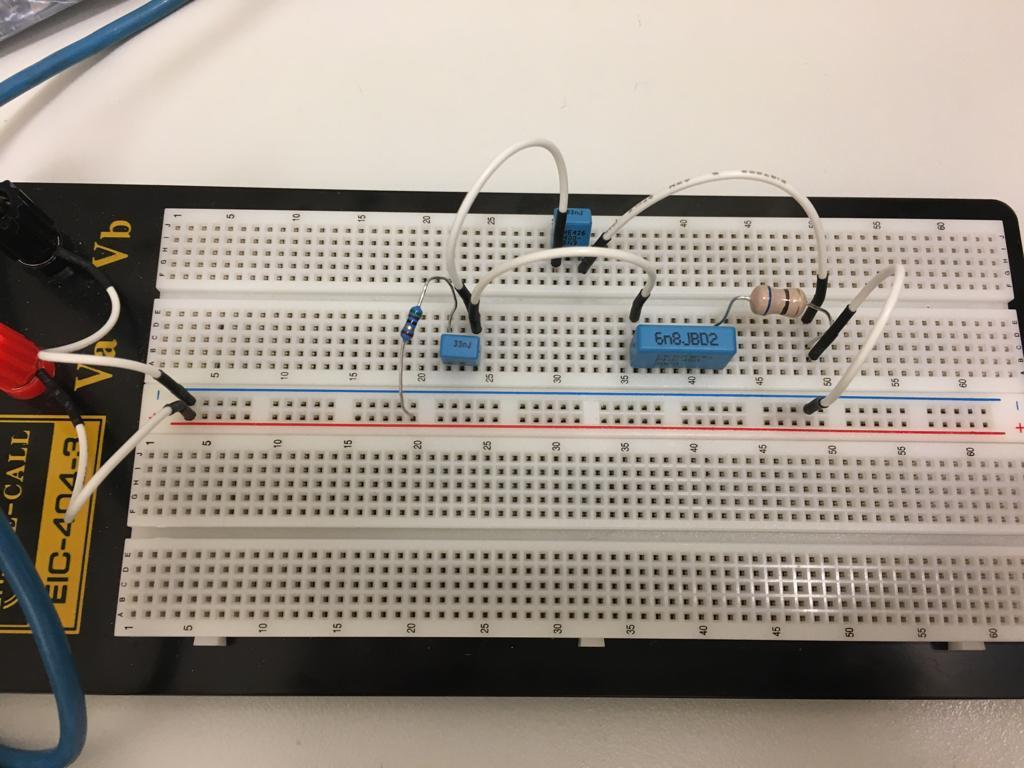

#### 12. Begründen Sie Ihr Vorgehen beim vorherigen Aufgabenteil. Geben Sie die Schaltung und den allgemeingultigen Dämpfungsverlauf des Hochpassfilters an.

Auf der Filtertabelle betrachten wir die Realisierung der Tiefpässe, da wir, wie in der vorherigen Aufgabe genannt, bestimmten Beschränkungen unterliegen. Müssen wir die Schaltung mit den vielen Induktivitäten wählen. 

Die Beschränkungen sind gleiche Bauteile und gleiche Ordnung. Und wir wissen aus der Vorlesung (siehe Skizze unten) wie man vom TP zum HP kommt. 

Da unsere TP Schaltung viele Kodensatoren hat, müssen wir ein HP bauen mit vielen Kodensatoren. Um Kodensatoren benutzen zu können gehen wir vom HP zu TP, also brauchen wir Spulen.

Kurz: Die Schaltung (TP) mit den vielen Induktivitäten aus dem Filterkatalog ist zu wählen. 

Aus der Vorlesung wissen wir:

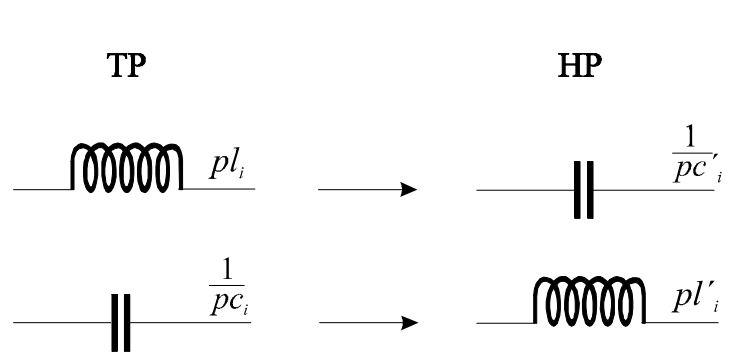 

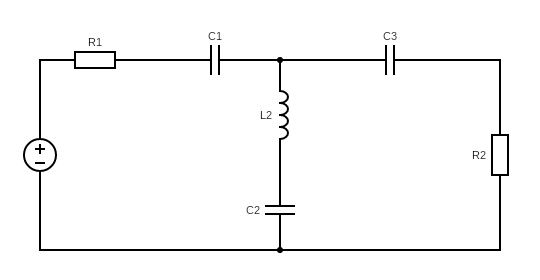

Allgemeiner Verlauf eines Cauer-Hochpasses 3.Ordnung